# One versus all

This question uses a subset of the iris data - only the sepal widths and sepal lengths for all three classes:

clear all;
load('exam_multiclass.mat', 'examples', 'labels');

This question is about training and visualising a set of Support Vector Machines (SVMs) in a one versus all (OVA) configuration in order to solve a multiclass problem. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score standardised.

Rather than using Matlab's built-in `fitcecoc()` function, you should develop your own function for training binary SVMs in an OVA configuration (see the `myova_fit()` stub, below). You should then add your own functions to: i) use the resulting model for prediction (see the `myova_predict()` stub, below); and ii) for visualisation (see the `visualiseSVMs()` stub, below). You can base your work on the example shown here: [https://www.mathworks.com/help/stats/fitcsvm.html#bt9ce5p-1](https://www.mathworks.com/help/stats/fitcsvm.html#bt9ce5p-1) 

Marks are available for:

- Extending the `myova_fit()` function to train a set of SVMs in an OVA configuration using the `examples` and `labels` that are passed in [4 marks]

- Extending the `myova_predict()` function to classify new `test_examples` using any model, `m`, trained by the `myova_fit()` function [4 marks]

- Extending the `visualiseSVMs()` function to give a helpful visualisation of any 2D model, `m`, trained by the `myova_fit()` function (the visualisation should at least include the decision boundaries and the original training data) [8 marks]

- Convincing yourself the three functions work as you expect by using the data provided to reproduce at least one of the OVA visualisations from the lecture slides [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
examples %display examples

examples = 150×2 table
    sepal_width    sepal_length
    ___________    ____________

       1.0156        -0.89767  
     -0.13154         -1.1392  
      0.32732         -1.3807  
     0.097889         -1.5015  
        1.245         -1.0184  
       1.9333        -0.53538  
      0.78617         -1.5015  
      0.78617         -1.0184  
     -0.36097          -1.743  
     0.097889         -1.1392  
       1.4745        -0.53538  
      0.78617           -1.26  
     -0.13154           -1.26  
     -0.13154         -1.8638  
       2.1627       -0.052331  
       3.0805        -0.17309  


labels %display labels

labels = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 


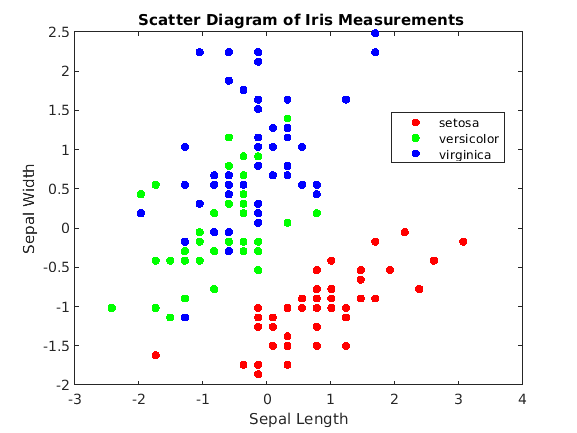

X = examples{:,:}; %set X to hold all examples
Y = labels; %set Y to hold all labels
figure
gscatter(X(:,1),X(:,2),Y); %scatter plot of both example columns giving labels as grouping

%add title and labels
title('{\bf Scatter Diagram of Iris Measurements}');
xlabel('Sepal Length');
ylabel('Sepal Width');


%call myova_fit() function
m = myova_fit(examples, labels)

m = struct with fields:
            X: [150×2 double]
            Y: [150×1 categorical]
    SVMModels: {3×1 cell}


predictions =    -0.2631   -0.4826   -0.4006
   -0.2629   -0.4813   -0.4034
   -0.2631   -0.4795   -0.4065
   -0.2639   -0.4769   -0.4100
   -0.2653   -0.4735   -0.4138
   -0.2674   -0.4691   -0.4180
   -0.2703   -0.4636   -0.4228
   -0.2742   -0.4570   -0.4280
   -0.2792   -0.4489   -0.4339
   -0.2852   -0.4393   -0.4405


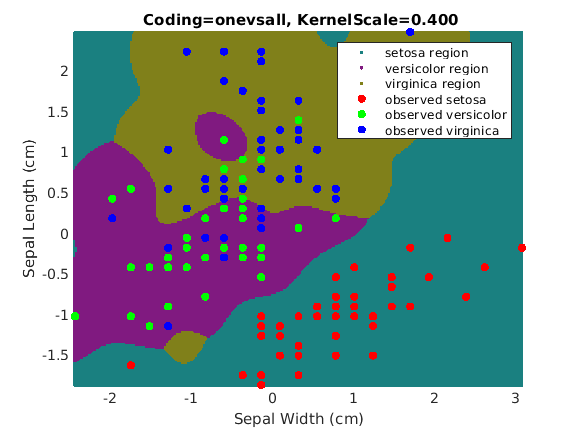

%call visualiseSVMs() function
visualiseSVMs(m)


%I have compared visualisation to lecture slide using ovevsall and
%kernelscale 0.4 and they seem identical 

function m = myova_fit(examples, labels)

    % Hint 1: if you plan to directly re-work the code from the link 
    % above, then storing the original training examples/labels inside
    % the model, in variables called X and Y, will help make the job 
    % a bit easier:
    m.X = examples{:,:};
    m.Y = labels;
    % Hint 2: note that our 'labels' variable is a categorical array
    % (as usual). So you can't compare against the values it holds 
    % using strcmp(), as in the example code, but you can use logical 
    % operators like ==

    % Add as many lines of code as you need below:
    
    m.SVMModels = cell(3,1); %setstructure (m) to store 3 SVMModels with a 3x1 cell
    classes = unique(m.Y); %find unique classes
    rng(1); % For reproducibility
    
    for j = 1:numel(classes)%loop over unqiue classes
        indx = (m.Y==classes(j)); % Create binary classes for each classifier (logical vector)
        %train SVM on each calss, store each trained classifier in
        %m.SVMModels using current index
        m.SVMModels{j} = fitcsvm(m.X,indx,'ClassNames',[false true],'Standardize',false,...
            'KernelFunction','rbf','BoxConstraint',1, 'KernelScale', 0.400);
    end
    
end

function predictions = myova_predict(m, xGrid)

    % Add as many lines of code as you need below:
    classes = unique(m.Y);
    N = size(xGrid,1);
    predictions = zeros(N,numel(classes));
    
    for j = 1:numel(classes) %loop over unqiue classes
        [~,score] = predict(m.SVMModels{j},xGrid); %predicte for each trained model given new 'observations' as the data
        predictions(:,j) = score(:,2); %second column contains positive-class scores
    end
    
end

function visualiseSVMs(m)

    % Add as many lines of code as you need below:
    %define a fine grid within the plot (every possible x and y value)
    %treated as new observation
    d = 0.02;
    [x1Grid,x2Grid] = meshgrid(min(m.X(:,1)):d:max(m.X(:,1)),...
        min(m.X(:,2)):d:max(m.X(:,2)));
    xGrid = [x1Grid(:),x2Grid(:)];
    
    %predict the score of each 'observation' from the previously defined
    %grid (test_examples)
    predictions = myova_predict(m, xGrid)
    
    %associate each new 'observation' with the classifier that gives it the maximum score
    [~,maxScore] = max(predictions,[],2);
    
    figure %new figure
    %plot new 'observations' with associated maximum score as grouping
    h(1:3) = gscatter(xGrid(:,1),xGrid(:,2),maxScore,...
        [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]);
    hold on
    %plot of both example columns giving labels as grouping
    h(4:6) = gscatter(m.X(:,1),m.X(:,2),m.Y);
    %add labels, title and legend
    title('{\bf Coding=onevsall, KernelScale=0.400}');
    xlabel('Sepal Width (cm)');
    ylabel('Sepal Length (cm)');
    legend(h,{'setosa region','versicolor region','virginica region',...
        'observed setosa','observed versicolor','observed virginica'},...
        'Location','Northeast');
    axis tight
    hold off

end